# MAS416 - Mechanical test level 2

## System 11

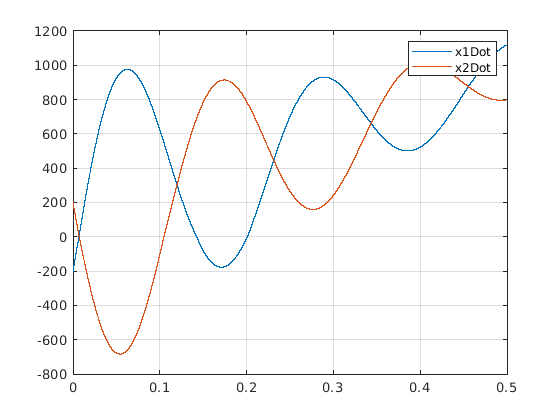

clc; clear all; close all;

m1 = 334; % kg
m2 = 366; % kg
m3 = 152; % kg
g = 9.81; % m/s^2

k1 = 340000; % N/m
L01 = 102/10^3; % m
b1 = 3200; % Ns/m

h1 = 362/10^3; % m
vt1 = 10/10^3; % m/s
muk1 = 0.3;
vt2 = 10/10^3; % m/s
muk2 = 0.2;

x1 = 72/10^3; % m
x1Dot = -200/10^3; % m/s

x2 = 605/10^3; % m
x2Dot = 200/10^3; % m/s

t = 0; % s
simTime = 0.5; % s
dt = 10^-5; % s
idx = 1; % Counter

while(t <= simTime)
    % Calculation

    delta = x2-h1-x1-L01;
    deltaDot = x2Dot-x1Dot;

    Fk = k1*delta;
    Fb = b1*deltaDot;

    mu1 = muk1 * tanh(x1Dot/vt1);
    mu2 = muk2 * tanh(x2Dot/vt2);

    Ffr1 = m1*g*mu1;
    Ffr2 = m2*g*mu2;
    Fg3 = m3*g;

    sumF1 = Fk+Fb+Ffr1+Fg3;
    sumF2 = -Fk-Fb-Ffr2+Fg3;

    x1DotDot = sumF1/(m1+m2+m3);
    x2DotDot = sumF2/(m1+m2+m3);

    % Logging
    t_plt(idx) = t;
    x1_plt(idx) = x1;
    x1Dot_plt(idx) = x1Dot;
    x2_plt(idx) = x2;
    x2Dot_plt(idx) = x2Dot;
    delta_plt(idx) = delta;
    mu1_plt(idx) = -Ffr1;
    Fk_plt(idx) = Fk;

    % Time integration
    x1Dot = x1Dot + x1DotDot * dt;
    x1 = x1 + x1Dot * dt;
    x2Dot = x2Dot + x2DotDot * dt;
    x2 = x2 + x2Dot * dt;

    % Update variables
    t = t + dt;
    idx = idx + 1;
end

plot(t_plt, x1Dot_plt*1000)
hold on
plot(t_plt, x2Dot_plt*1000)
% plot(t_plt, mu1_plt)
% plot(t_plt, Fk_plt)
legend("x1Dot", "x2Dot")
grid

hold off

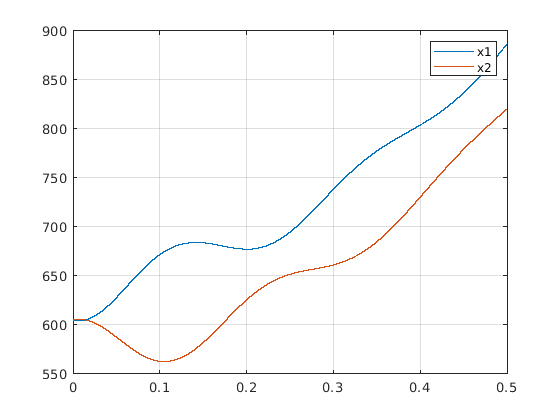

plot(t_plt, x1_plt*1000-72+605)
hold on
plot(t_plt, x2_plt*1000)
legend("x1", "x2")
grid

hold off

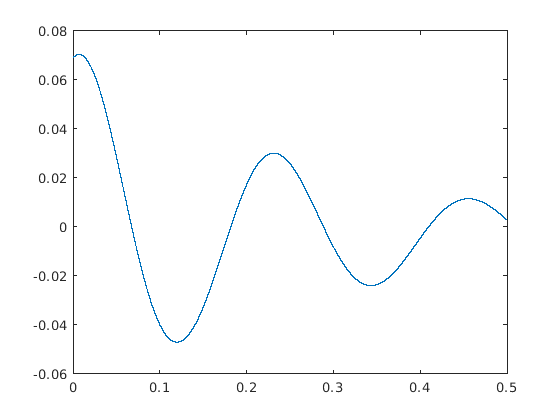

plot(t_plt, delta_plt)

hold off

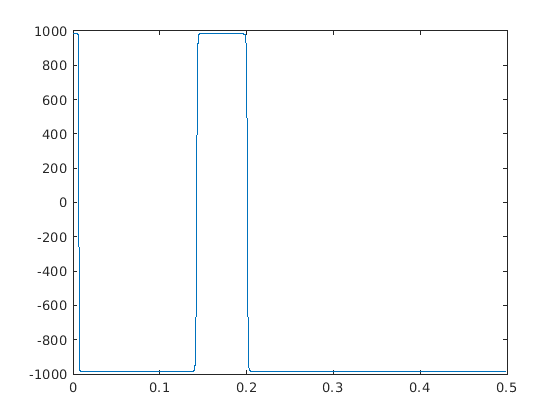

plot(t_plt, mu1_plt)


disp("What is the maximum absolute value of the velocity [mm/s] of body m1 ?")

What is the maximum absolute value of the velocity [mm/s] of body m1 ?


x1Dot_max = max(x1Dot_plt*1000)

x1Dot_max =           1120.13362532726


x1Dot_min = min(x1Dot_plt*1000)

x1Dot_min =   -200


% Not correct solution :(